# Hailing Ileum Test

run_id = 'max';

input_path = 'D:/2021-01-17-Hailing-Ileum/';
input_dim = [3072 3072 45 4 6];
gpu_block = [1024 1024 45 4 6];
useGPU = true;

data_dirs = dir(fullfile(input_path, "round1", "Position*"));
data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name)

% data_dirs = data_dirs(1:1)

Ndirs = numel(data_dirs);
upd_1 = textprogressbar(Ndirs, 'updatestep', 1);

for p=1:Ndirs

    curr_data_dir = data_dirs{p};
    curr_out_path = fullfile(input_path, 'output', run_id, curr_data_dir)

    if ~exist(curr_out_path, 'dir')
        mkdir(curr_out_path)
    end
               
    sdata_start = tic;
    sdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
    sdata.log = fopen(fullfile(curr_out_path, 'log.txt'), 'w');
    fprintf(sdata.log, sprintf("====Current Position: %s====\n", curr_data_dir));
    sdata = sdata.LoadRawImages('sub_dir', curr_data_dir, 'input_dim', input_dim);
    sdata = sdata.SwapChannels; % !!
    sdata = sdata.MinMaxNormalize;
    sdata = sdata.HistEqualize('Method', "inter_round");
    sdata = sdata.HistEqualize('Method', "intra_round");
    sdata = sdata.MorphoRecon('Method', "2d", 'radius', 3);
    sdata = sdata.test_GlobalRegistration('useGPU', false);
    
    cell_imgs = RegisterCellImage(sdata, input_path, 'reg', curr_data_dir, 3, false);
    
    gpu_overlap = 0;
    gb_idx = BlockTest(sdata.rawImages, gpu_block, gpu_overlap);
    NgpuBlock = numel(gb_idx)
    upd_2 = textprogressbar(NgpuBlock, 'updatestep', 1);

    goodSpots = [];
    goodReads = [];
    total_score = [];
    total_counts = 0;
    
    for i =1:NgpuBlock
        
        bdata_start = tic;
        gpu_idx = gb_idx{i}
        
        fprintf(sdata.log, sprintf("====Current Block: %d====\n", i));
        fprintf(sdata.log, sprintf("Index: %d - %d - %d - %d\n", gpu_idx));
        
        bdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
        bdata.log = sdata.log;
        bdata = bdata.LoadDim(gpu_block);
        bdata.registeredImages = sdata.registeredImages(...
            gpu_idx(1,1):gpu_idx(1,2),...
            gpu_idx(2,1):gpu_idx(2,2),...
            :,:,:);
        
        bdata = bdata.xxx_LocalRegistration('Iterations', 50, 'AccumulatedFieldSmoothing', 1);
        
        % replace the old image 
        sdata.registeredImages(...
            gpu_idx(1,1):gpu_idx(1,2),...
            gpu_idx(2,1):gpu_idx(2,2),...
            :,:,:) = bdata.registeredImages;
            
        bdata = bdata.LoadCodebook;
        bdata = bdata.SpotFinding('Method', "max3d", 'ref_index', 1,  'qualityThreshold', 0.01, ...
                'volumeThreshold', 30, 'barcodeMethod', "iteration", 'showPlots', false);
        bdata = bdata.ReadsExtraction('showPlots', false, 'voxelSize', [2 2 1]); 
        bdata = bdata.ReadsFiltration('showPlots', false);
        
        block_offsets = [gpu_idx(2,1) - 1 gpu_idx(1,1) - 1 0]
        if size(bdata.goodSpots, 1) ~= 0
            block_offsets = repmat(block_offsets, size(bdata.goodSpots, 1), 1);
            bdata.allSpots = bdata.goodSpots + int16(block_offsets);
        end
        
        % Update tile reads
        goodSpots = [goodSpots; bdata.goodSpots];
        goodReads = [goodReads; bdata.goodReads];
        total_score = [total_score; bdata.FilterScores];
        total_counts = total_counts + size(bdata.goodSpots, 1);
        
        fprintf(sprintf("====Block %d Finished [time=%02f]====", i, toc(bdata_start)));
        upd_2(i);
    end

    % Save registered image
    output_dir = fullfile(curr_out_path, 'registered_image');
    if ~exist(output_dir, 'dir')
       mkdir(output_dir);
    end
    new_SaveImg(output_dir, sdata.registeredImages);

    % Save cell image
    output_dir = fullfile(input_path, 'output', run_id);
    if ~exist(output_dir, 'dir')
       mkdir(output_dir);
    end
    SaveCellImg(output_dir, cell_imgs, curr_data_dir, ["dapi", "protein", "merged_dots"]);
    
        
    % Save points 
    save(fullfile(curr_out_path, strcat('goodPoints_max3d.mat')), 'goodReads', 'goodSpots');
    
    fprintf(sprintf("====%s Finished [time=%02f]====", curr_data_dir, toc(sdata_start)));
    fprintf(sdata.log, sprintf("====%s Finished [time=%02f]====", curr_data_dir, toc(sdata_start)));
    
    reset(gpuDevice)
    fclose(sdata.log);
    upd_1(p);
    
end

## Plot dots on DAPI

curr_data_dir = 'Position001'

npoints = 22201

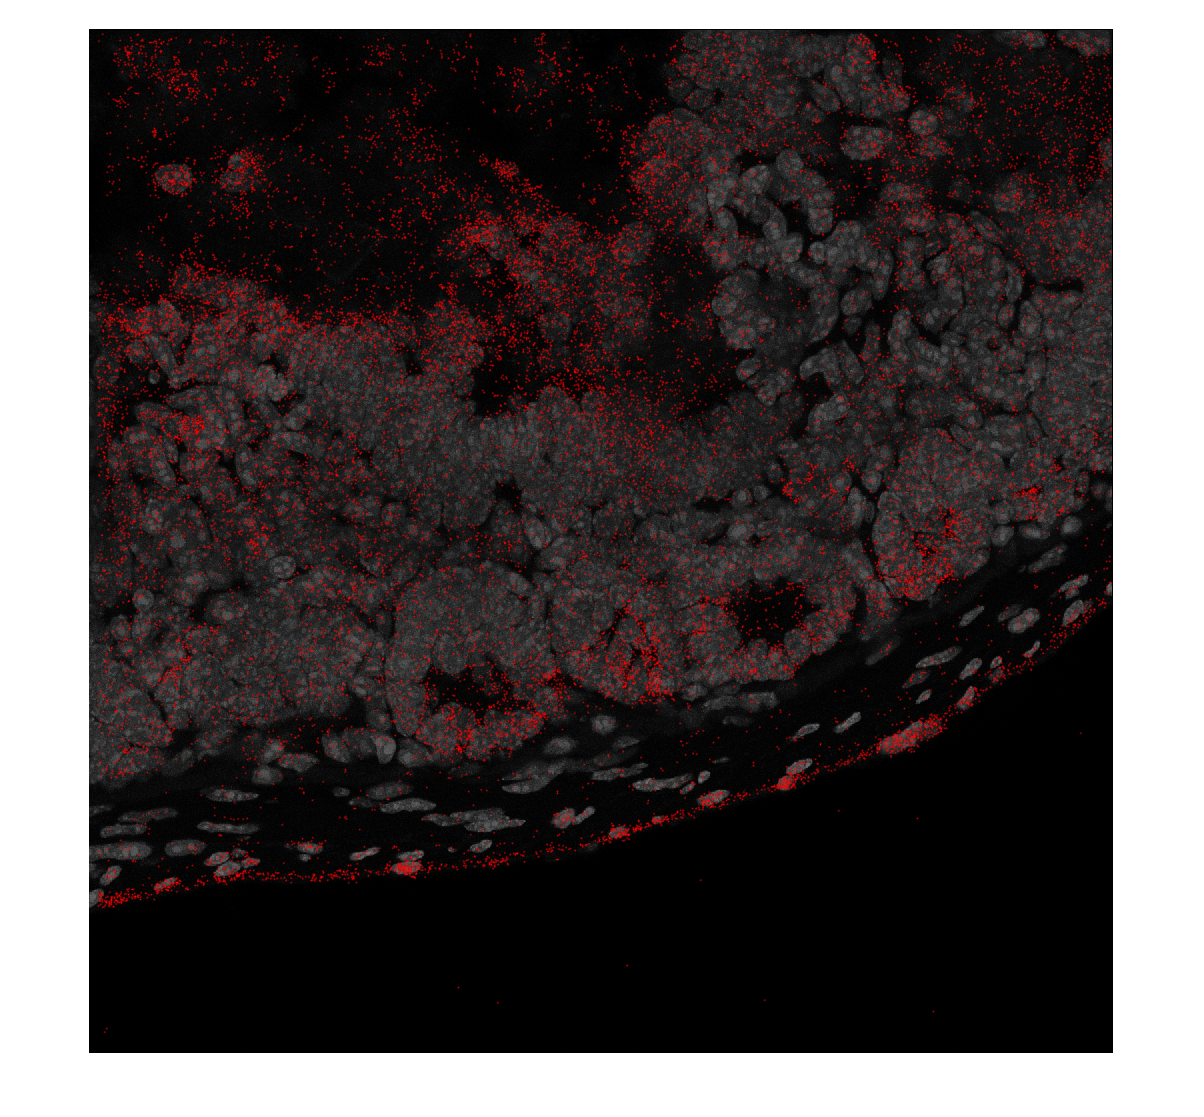

====Position001 Finished [time=5.616800]====

saveAS = true;

for p=1:Ndirs
    starting = tic;
    curr_data_dir = data_dirs{p}
    curr_out_path = fullfile(input_path, 'output', run_id, curr_data_dir);
    curr_dapi_path = fullfile(input_path, 'output', run_id, 'dapi');
    
    curr_dapi_file = fullfile(curr_dapi_path, sprintf('%s.tif', curr_data_dir));
    curr_dapi_img = new_LoadMultipageTiff(curr_dapi_file, 'uint8', 'uint8', false);
    curr_dapi_img = max(curr_dapi_img, [], 3);
    
    curr_dot_path = fullfile(curr_out_path, "goodPoints_max3d.mat");
    load(curr_dot_path);
    
    img_out_path = fullfile(input_path, 'output', run_id, 'dots_on_dapi');

    if ~exist(img_out_path, 'dir')
        mkdir(img_out_path)
    end
    
    good_points = goodSpots;
%     good_points = ismember(goodReads, seq);
%     good_points = goodSpots(good_points, :);

    npoints = size(good_points, 1)
    
%     fh = figure('Position', [0 0 3072 3072]);
%     ah = axes('Units','Normalize','Position', [0 0 1 1]);
    figure
    imshow(curr_dapi_img)
    hold on
    plot(good_points(:,1), good_points(:,2), '.', "Color", 'red', "MarkerSize", 1)
    hold off
%     axis(ah, 'square');
%     fh.Position(3) = fh.Position(4)
    fig_name = fullfile(img_out_path, sprintf("%s.png", curr_data_dir));
    export_fig(fig_name)


    
    fprintf(sprintf("====%s Finished [time=%02f]====", curr_data_dir, toc(starting)));
    
    
end

## Save good spots

run_id = 'max';

input_path = 'D:/2021-01-17-Hailing-Ileum/';

data_dirs = dir(fullfile(input_path, "round1", "Position*"));
data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name)

data_dirs = 79×1 cell array
    {'Position001'}
    {'Position002'}
    {'Position003'}
    {'Position004'}
    {'Position005'}
    {'Position006'}
    {'Position007'}
    {'Position008'}
    {'Position009'}
    {'Position010'}
    {'Position011'}
    {'Position012'}
    {'Position013'}
    {'Position014'}
    {'Position015'}
    {'Position016'}
    {'Position017'}
    {'Position018'}
    {'Position019'}
    {'Position020'}
    {'Position021'}
    {'Position022'}
    {'Position023'}
    {'Position024'}
    {'Position025'}
    {'Position026'}
    {'Position027'}
    {'Position028'}
    {'Position029'}
    {'Position030'}



% data_dirs = data_dirs(1:1)

Ndirs = numel(data_dirs);
upd_1 = textprogressbar(Ndirs, 'updatestep', 1);

Completed [                    ]   0% --:--:--


for p=1:Ndirs

    curr_data_dir = data_dirs{p};
    curr_out_path = fullfile(input_path, 'output', run_id, curr_data_dir)

    if ~exist(curr_out_path, 'dir')
        mkdir(curr_out_path)
    end
               
    sdata = new_STARMapDataset(input_path, 'useGPU', false);
    sdata.log = fopen(fullfile(curr_out_path, 'log_bk.txt'), 'w');
    sdata = sdata.LoadCodebook;
    curr_dot_path = fullfile(curr_out_path, "goodPoints_max3d.mat");
    load(curr_dot_path);
    
    sdata.allSpots = goodSpots;
    sdata.allReads = goodReads;
    
    sdata = sdata.ReadsFiltration('showPlots', false);
    
    goodSpots = sdata.goodSpots;
    goodReads = sdata.goodReads;
    
    % Save points 
    save(fullfile(curr_out_path, strcat('goodPoints_max3d_bk.mat')), 'goodReads', 'goodSpots');
    
end

curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position001'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
1.000000 [16598 / 16598] percent of good reads are in codebook
Inf [16598 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position002'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
1.000000 [34850 / 34850] percent of good reads are in codebook
Inf [34850 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position003'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.786851 [15283 / 19423] percent of good reads are in codebook
Inf [15283 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position004'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.751195 [39745 / 52909] percent of good reads are in codebook
Inf [39745 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position005'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.773887 [61798 / 79854] percent of good reads are in codebook
Inf [61798 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position006'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.837464 [32775 / 39136] percent of good reads are in codebook
Inf [32775 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position007'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.839322 [4158 / 4954] percent of good reads are in codebook
Inf [4158 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position008'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.805688 [31504 / 39102] percent of good reads are in codebook
Inf [31504 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position009'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.802933 [66075 / 82292] percent of good reads are in codebook
Inf [66075 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position010'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.803348 [54712 / 68105] percent of good reads are in codebook
Inf [54712 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position011'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.817332 [29983 / 36684] percent of good reads are in codebook
Inf [29983 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position012'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.823661 [5904 / 7168] percent of good reads are in codebook
Inf [5904 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position013'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.829680 [29184 / 35175] percent of good reads are in codebook
Inf [29184 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position014'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.811930 [32055 / 39480] percent of good reads are in codebook
Inf [32055 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position015'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.826363 [41338 / 50024] percent of good reads are in codebook
Inf [41338 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position016'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.832886 [38192 / 45855] percent of good reads are in codebook
Inf [38192 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position017'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.852153 [43718 / 51303] percent of good reads are in codebook
Inf [43718 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position018'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.826077 [31533 / 38172] percent of good reads are in codebook
Inf [31533 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position019'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.816568 [29020 / 35539] percent of good reads are in codebook
Inf [29020 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position020'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.803144 [31680 / 39445] percent of good reads are in codebook
Inf [31680 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position021'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.828834 [19156 / 23112] percent of good reads are in codebook
Inf [19156 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position022'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.839516 [36367 / 43319] percent of good reads are in codebook
Inf [36367 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position023'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.836025 [20552 / 24583] percent of good reads are in codebook
Inf [20552 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position024'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.836050 [7797 / 9326] percent of good reads are in codebook
Inf [7797 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position025'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.847327 [21223 / 25047] percent of good reads are in codebook
Inf [21223 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position026'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.854114 [30696 / 35939] percent of good reads are in codebook
Inf [30696 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position027'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.849377 [24079 / 28349] percent of good reads are in codebook
Inf [24079 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position028'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.852598 [14981 / 17571] percent of good reads are in codebook
Inf [14981 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position029'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.815060 [35037 / 42987] percent of good reads are in codebook
Inf [35037 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position030'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.771498 [16831 / 21816] percent of good reads are in codebook
Inf [16831 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position031'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.748741 [71832 / 95937] percent of good reads are in codebook
Inf [71832 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position032'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.792399 [48643 / 61387] percent of good reads are in codebook
Inf [48643 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position033'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.762380 [51758 / 67890] percent of good reads are in codebook
Inf [51758 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position034'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.717199 [92566 / 129066] percent of good reads are in codebook
Inf [92566 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position035'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.698585 [97308 / 139293] percent of good reads are in codebook
Inf [97308 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position036'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.785091 [49237 / 62715] percent of good reads are in codebook
Inf [49237 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position037'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.774070 [31082 / 40154] percent of good reads are in codebook
Inf [31082 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position038'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.755874 [67080 / 88745] percent of good reads are in codebook
Inf [67080 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position039'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.795709 [40796 / 51270] percent of good reads are in codebook
Inf [40796 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position040'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.754403 [13408 / 17773] percent of good reads are in codebook
Inf [13408 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position041'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.861622 [8244 / 9568] percent of good reads are in codebook
Inf [8244 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position042'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.863351 [24615 / 28511] percent of good reads are in codebook
Inf [24615 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position043'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.863600 [23768 / 27522] percent of good reads are in codebook
Inf [23768 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position044'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.854161 [12481 / 14612] percent of good reads are in codebook
Inf [12481 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position045'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.858349 [26335 / 30681] percent of good reads are in codebook
Inf [26335 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position046'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.833862 [6831 / 8192] percent of good reads are in codebook
Inf [6831 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position047'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.885634 [9161 / 10344] percent of good reads are in codebook
Inf [9161 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position048'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.854053 [37867 / 44338] percent of good reads are in codebook
Inf [37867 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position054'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.834638 [19513 / 23379] percent of good reads are in codebook
Inf [19513 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position055'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.863927 [17701 / 20489] percent of good reads are in codebook
Inf [17701 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position056'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.906491 [5293 / 5839] percent of good reads are in codebook
Inf [5293 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position057'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.890160 [16727 / 18791] percent of good reads are in codebook
Inf [16727 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position058'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.861577 [21679 / 25162] percent of good reads are in codebook
Inf [21679 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position059'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.849629 [20499 / 24127] percent of good reads are in codebook
Inf [20499 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position060'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.869955 [776 / 892] percent of good reads are in codebook
Inf [776 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position061'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.861885 [19083 / 22141] percent of good reads are in codebook
Inf [19083 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position062'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.865173 [29890 / 34548] percent of good reads are in codebook
Inf [29890 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position063'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.859891 [10059 / 11698] percent of good reads are in codebook
Inf [10059 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position064'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.841948 [31275 / 37146] percent of good reads are in codebook
Inf [31275 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position065'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.785661 [49917 / 63535] percent of good reads are in codebook
Inf [49917 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position066'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.811170 [22179 / 27342] percent of good reads are in codebook
Inf [22179 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position067'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.835417 [50658 / 60638] percent of good reads are in codebook
Inf [50658 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position068'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.795661 [77425 / 97309] percent of good reads are in codebook
Inf [77425 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position069'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.847810 [33402 / 39398] percent of good reads are in codebook
Inf [33402 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position070'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.848082 [22090 / 26047] percent of good reads are in codebook
Inf [22090 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position071'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.854127 [44752 / 52395] percent of good reads are in codebook
Inf [44752 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position072'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.864635 [15662 / 18114] percent of good reads are in codebook
Inf [15662 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position073'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.853452 [29963 / 35108] percent of good reads are in codebook
Inf [29963 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position074'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.853140 [53561 / 62781] percent of good reads are in codebook
Inf [53561 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position075'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.831098 [59416 / 71491] percent of good reads are in codebook
Inf [59416 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position076'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.856414 [52338 / 61113] percent of good reads are in codebook
Inf [52338 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position077'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.842048 [37845 / 44944] percent of good reads are in codebook
Inf [37845 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position078'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.849347 [60826 / 71615] percent of good reads are in codebook
Inf [60826 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position079'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.851857 [56427 / 66240] percent of good reads are in codebook
Inf [56427 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position080'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.859114 [40844 / 47542] percent of good reads are in codebook
Inf [40844 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position081'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.851392 [23518 / 27623] percent of good reads are in codebook
Inf [23518 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position082'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.856826 [42939 / 50114] percent of good reads are in codebook
Inf [42939 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position083'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.839680 [30100 / 35847] percent of good reads are in codebook
Inf [30100 / 0] percent of CNNNNNC reads are in codebook


curr_out_path = 'D:\2021-01-17-Hailing-Ileum\output\max\Position084'

Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
NaN [0 / 0] percent of good reads are CNNNNNC
0.833944 [4555 / 5462] percent of good reads are in codebook
Inf [4555 / 0] percent of CNNNNNC reads are in codebook
